# Defect analysis

TODO describe ......  intro to technological problem (research something about mechanical ... ask diego maybe). Explain analysis....

globals();
global augmented_dataset_path variables_analytics_defects_statistics_path; % data
global number_defect_classes image_size; % data info
global column_encoded_pixels; % columns

% Load dataset
opts = detectImportOptions(augmented_dataset_path);
dataset = readtable(augmented_dataset_path , opts);

% printing utils
% lengths = -image_size(2):0.5:image_size(2);
% heights = -image_size(1):0.5:image_size(1);
% [H,L] = meshgrid(heights,lengths);
% X = [H(:) L(:)];

## Distribution map

TODO explain .....

## Bivariate gaussian distribution

TODO describe why... conv filters sizing ...

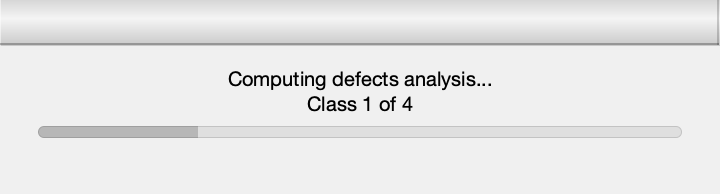

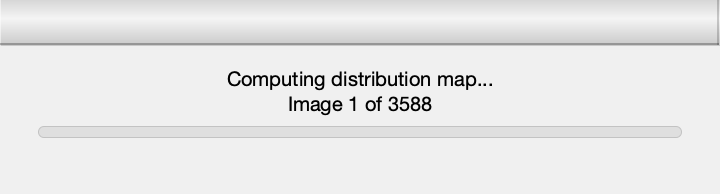

Undefined function or variable 'bounding_boxes'.

Error in map2distribution_map (line 48)
        lh_region = diff(bounding_boxes);

% Distribution maps
distribution_maps = zeros(image_size(1), image_size(2), number_defect_classes);
% Gaussian parameters % TODO properly pre-allocate
means = zeros(1,2,number_defect_classes); covs = zeros(2,2,number_defect_classes);
defect_analysis_waitbar = waitbar(0, "Computing defects analysis...");
for class_id = 1 : number_defect_classes
    waitbar(class_id / number_defect_classes, defect_analysis_waitbar, ...
        sprintf("Computing defects analysis...\nClass %d of %d",class_id,number_defect_classes));
    column_name = sprintf("%s%d",column_encoded_pixels,class_id);
    classdata = dataset{strcmp(dataset{:,column_name},"") == 0,column_name};
    [distribution_maps(:,:,class_id),means(:,:,class_id),covs(:,:,class_id)] = map2distribution_map(string(classdata), image_size);
    % done inside for loop to backup
    save(variables_analytics_defects_statistics_path,"distribution_maps","means","covs");
end

close(defect_analysis_waitbar);

% Remark: there is no script for lh1,lh2,lh3,lh4.. however they are
% calculated with map2distribution
load(variables_analytics_defects_statistics_path);

## Class 1

TODO try to understand what kind of defects is

figure;
% Print distribution_map
imagesc(ceil(distribution_maps(:,:,1)*255));
% Print statistical distribution
distribution_plot(lh1);

## Class 2

TODO try to understand what kind of defects is

figure;
% Print distribution_map
imagesc(ceil(distribution_maps(:,:,2)*255));
% Print statistical distribution
distribution_plot(lh2);

## Class 3

TODO try to understand what kind of defects is

figure;
% Print distribution_map
imagesc(ceil(distribution_maps(:,:,3)*255));
% Print statistical distribution
distribution_plot(lh2);

## Class 4

TODO try to understand what kind of defects is

figure;
% Print distribution_map
imagesc(ceil(distribution_maps(:,:,4)*255));
% Print statistical distribution
distribution_plot(lh2);